M130 Lab 2

Start by checking the image properties of your assigned image and loading it into MATLAB

%Refer to the examples and the tutorial file for this
%Remember to use imfinfo to see what the image size is
%create the placeholder variable with 'zeros' and use a 
%for loop to read in the data

info = imfinfo('Image_7.tif'); 
info(1).Width

ans = 768

info(1).Height 

ans = 768

info(1).ColorType 

ans = 'grayscale'

info(1).BitDepth

ans = 16


%find out how many pages 
length(info)

ans = 20


disp("The size of image is 768x768, with 20 pages")

The size of image is 768x768, with 20 pages



img = zeros(info(1).Height,info(1).Width,length(info),'uint16');
% creates a matrix, with three dimensions (rows = 768, column = 768, pages = 20 ). Any
% number between 1 to 20 should be fine 

for i = 1:length(info)
    img(:,:,i) = imread('Image_7.tif',i); 
end

size(img)

ans =    768   768    20


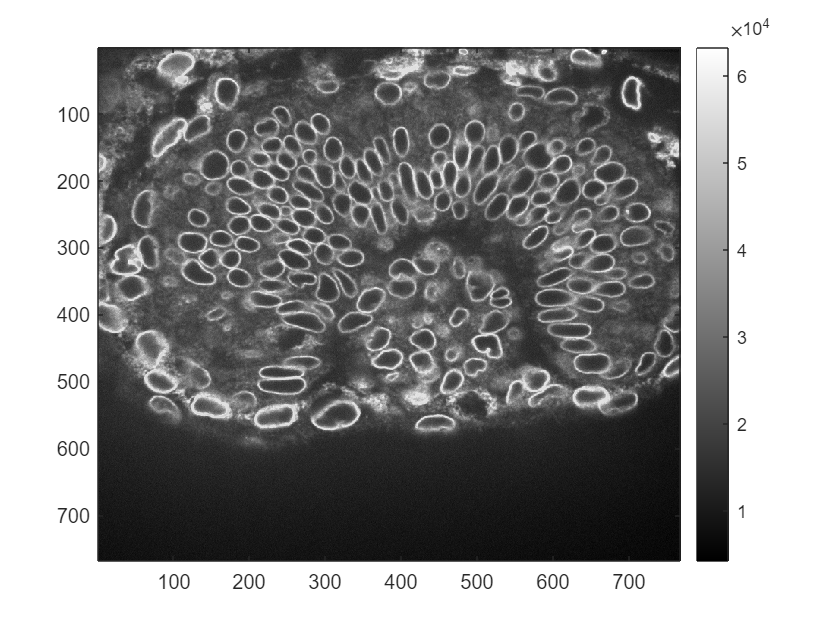

%Display your image, either as a max projection, using subplot, or 
%using the slice viewer 1 point
imagesc(img(:,:,1)) % display specific page of the image
colormap gray %legend that interprets pixel brightness
colorbar 

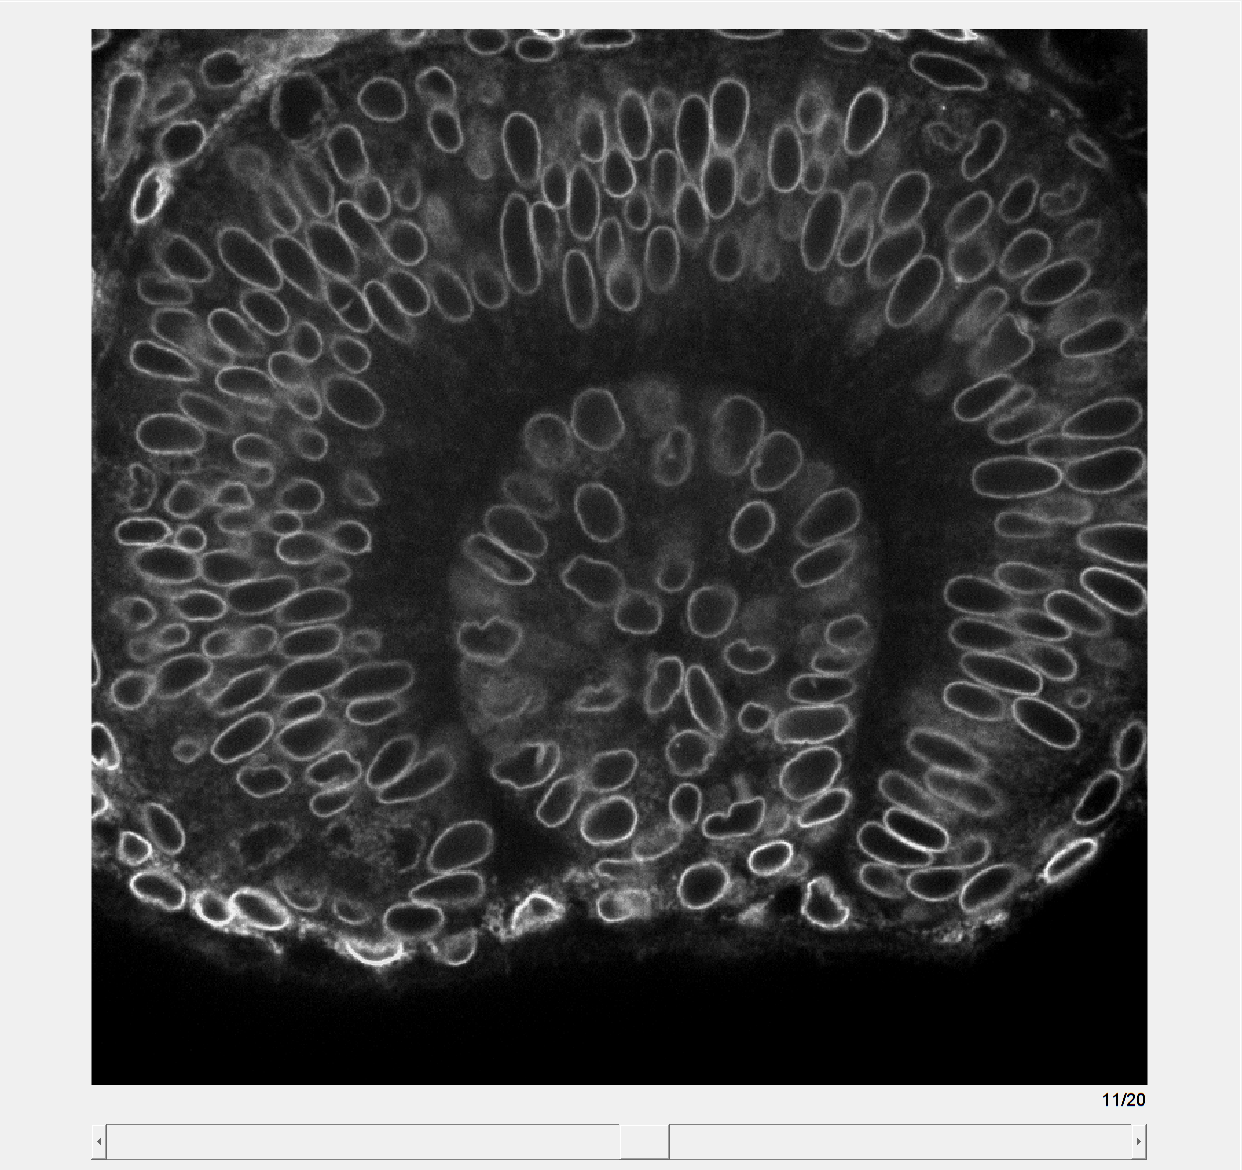

ans =   sliceViewer with properties:

             SliceDirection: [0 0 1]
                SliceNumber: 11
                     Parent: [1×1 Panel]
                   Colormap: [256×3 double]
               DisplayRange: [10000 60000]
               ScaleFactors: [1 1 1]
    DisplayRangeInteraction: 'on'



%Because colorbar shows range from 10000 to 60000, 
% we can display it on sliceViewer

%sliceviewer 
sliceViewer(img, "DisplayRange", [10000, 60000])

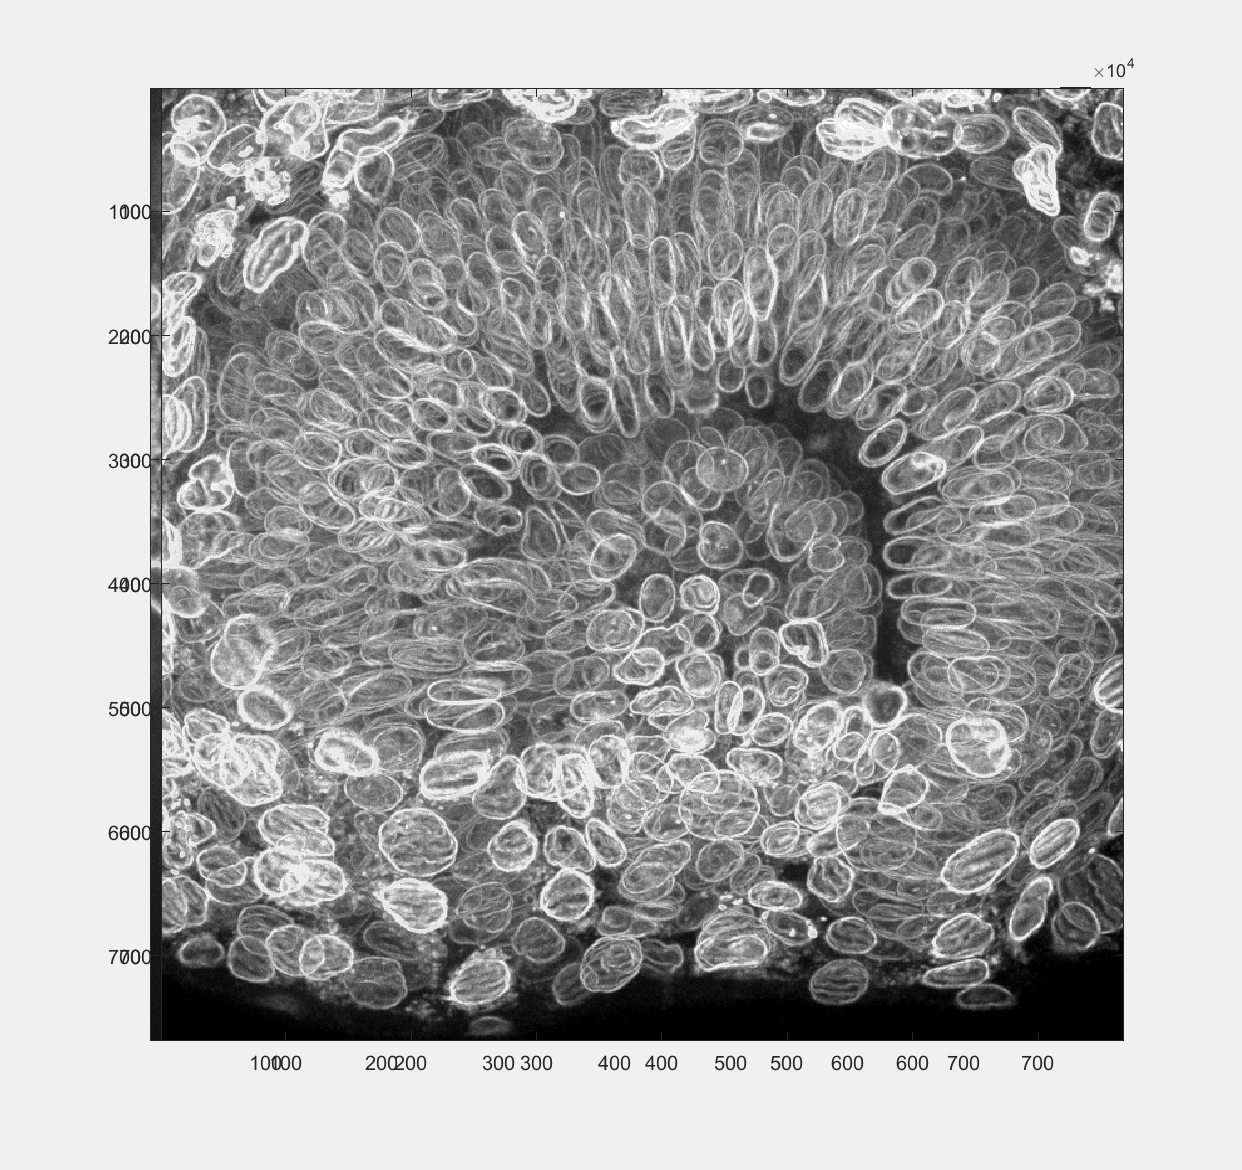


%max projection displays the maximum intensity across all slices in 3D. 
% Use dim input to the max function to calcualte the 2D max 
max_proj = max(img, [], 3); 
imagesc(max_proj, [10000, 60000])

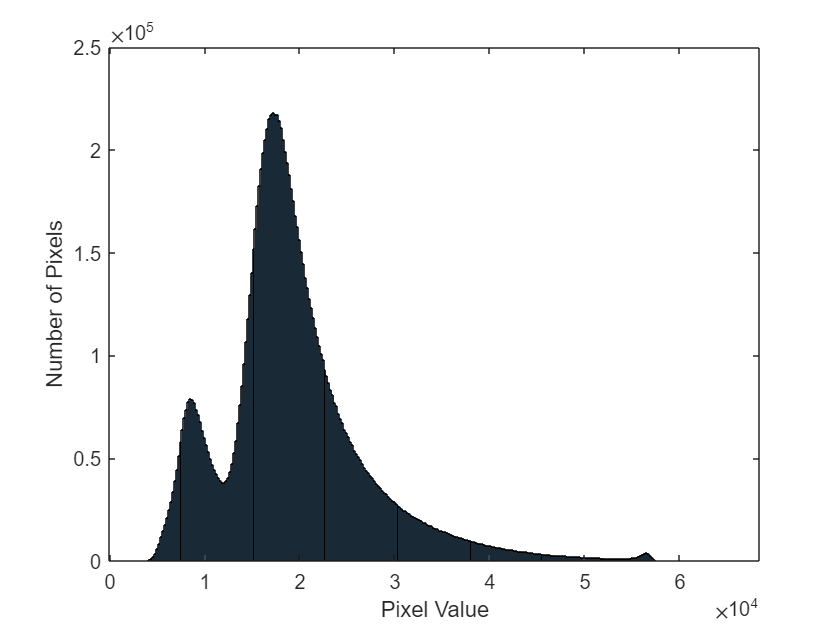

%Calculate Weber's contrast for this image. To classify foreground and
%background pixels, generate a histogram of the whole volume and pick a
%reasonable threshold. To visualize the foreground / background maps, use
%imagesc to display a max projection of the foreground and background
%images themselves. 2 points

%Remember that Weber's contrast is:
%(I_foreground - I_background) / %I_background

% step 1: Generation of histogram
figure;
histogram(double(img(:)),300) 
xlabel('Pixel Value')
ylabel('Number of Pixels')

% step 2: Pick threshold value 

thresh = 35000;
foreground = img>thresh; 
background = img<=thresh;

pixels_in_foregnd = sum(foreground(:))

pixels_in_foregnd = 513391

pixels_in_backgnd = sum(background(:))

pixels_in_backgnd = 11283089

ratio = pixels_in_foregnd/pixels_in_backgnd  %summation of pixel, take a ratio 

ratio = 0.0455

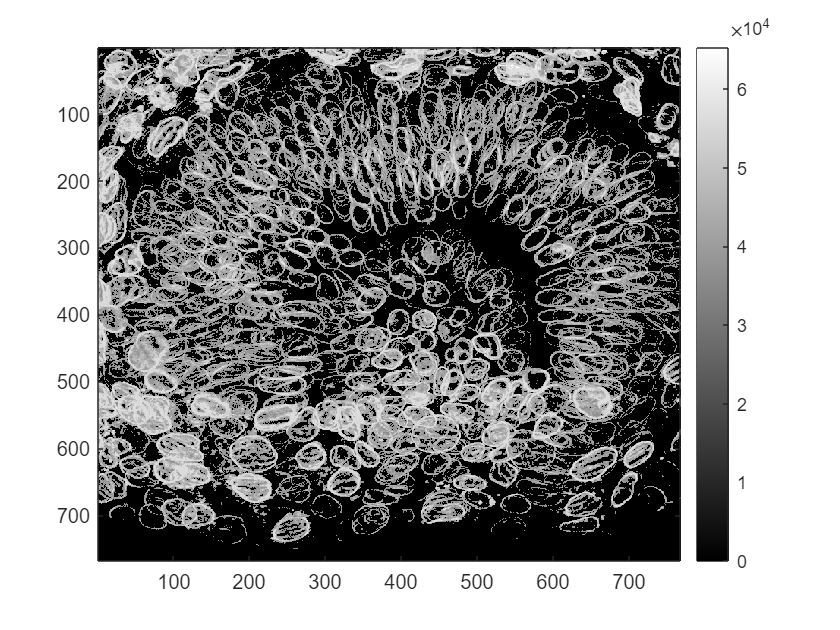


foregnd_img = img.*uint16(foreground);

max_proj_foregnd = max(foregnd_img,[],3);
imagesc(max_proj_foregnd)
colormap gray
colorbar

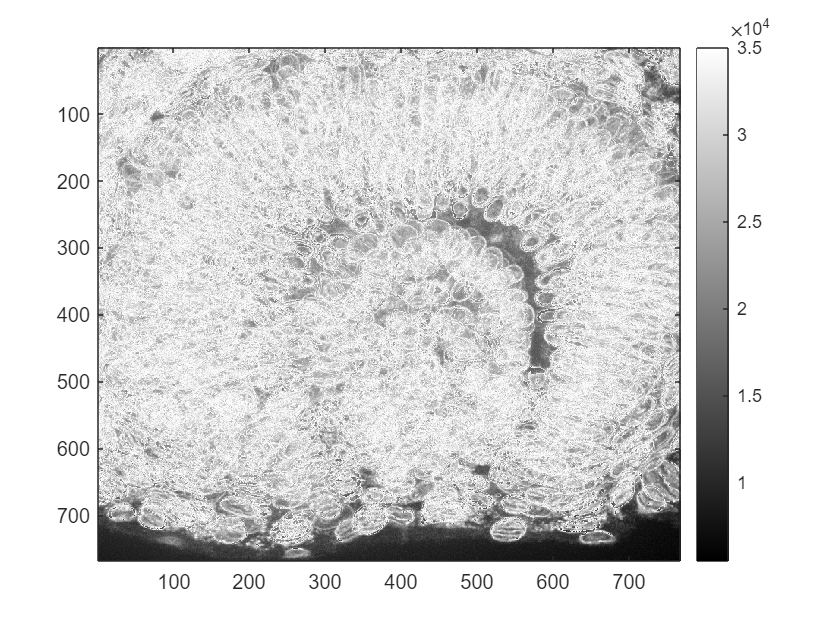

backgnd_img = img.*uint16(background);


max_proj_backgnd = max(backgnd_img,[],3);
imagesc(max_proj_backgnd)
colormap gray
colorbar


mean_img_bkgnd = mean(img(background));
mean_img_fgnd = mean(img(foreground));
Weber = (mean_img_fgnd- mean_img_bkgnd)/mean_img_bkgnd

Weber = 1.2730


disp("The Weber contrast is 1.27")

The Weber contrast is 1.27


%Calculate Michelson contrast for the image. Remember that it is:
% (I_max - I_min) / (I_max + I_min) 2 points

I_max = max(double(img(:)))

I_max = 65326

disp(I_max)

       65326




I_min = min(double(img(:)))

I_min = 3167

disp(I_min)

        3167



Michelson = double((I_max - I_min)/(I_max + I_min))

Michelson = 0.9075

max_proj = max(img,[],3);
Michelson_max_project = double(max(max_proj(:)) - min(max_proj(:)))/double(max(max_proj(:)) + min(max_proj(:)))

Michelson_max_project = 0.9134


Michelson = double(max(img(:)) - min(img(:)))/double(max(img(:)) + min(img(:)))

Michelson = 0.9485

% This non-max projection value is higher because max projection is
% collapsing 35 images into one. When we are calculating
% everything without max projection, we lose lower pixelated values. The global minimum is eliminated 
% so therefore we yield smaller contrast. 

disp("The Michelson max projection contrast is 0.9134, regular Michelson is 0.9485")

The Michelson max projection contrast is 0.9134, regular Michelson is 0.9485


%Calculate the RMS contrast for the image 2 points
RMS = sqrt(1/double(info(1).Width*info(1).Height)*double(sum(sum((max_proj - mean(max_proj(:))).^2))))

RMS = 179.3945

% All images' RMS, 0 to 20 pages 
sqrt(1/double(info(1).Width*info(1).Height)*double(sum(sum((img - mean(img(:))).^2))))

ans = ans(:,:,1) =

  192.2852


ans(:,:,2) =

  178.4373


ans(:,:,3) =

  178.4081


ans(:,:,4) =

  175.9022


ans(:,:,5) =

  174.0048


ans(:,:,6) =

  171.4927


ans(:,:,7) =

  171.4579


ans(:,:,8) =

  169.6293


ans(:,:,9) =

  169.1899


ans(:,:,10) =

  166.8112


ans(:,:,11) =

  164.0209


ans(:,:,12) =

  158.9760


ans(:,:,13) =

  156.6933


ans(:,:,14) =

  154.6660


ans(:,:,15) =

  153.8087


ans(:,:,16) =

  147.5912


ans(:,:,17) =

  143.7291


ans(:,:,18) =

  141.5048


ans(:,:,19) =

  134.9522


ans(:,:,20) =

  133.3992


RMS_volume = sqrt(sum(sum(sum((img - mean(img(:))).^2))))

RMS_volume = 5.5841e+05

disp("The max projectiont RMS contrast is 179.39"); 

The max projectiont RMS contrast is 179.39


Based on what we discussed in lecture, what you see in the image, pick one of these metrics that you feel is more appropriate for your image (there's no one right answer, but explain your choice a bit) (2 points)

In this specific example, the individual cells were most recognizable by caliberating the threshold in the Weber method. Both the Michelson and RMS method do not yield as much contrast (Weber yields up to 3 times more contrast). I should note here that the Weber metric would not be as appropriate if the image is primarily dark (most background is not showing features), and the Weber method is preferred here because we can see the foreground. While the Michelson method does not get impeded by user's need to define heuristics of foreground and background, it is not appropriate for this image. The RMS method is used if there are proportional foreground and background number of pixels, which is not what we see here (we have an abundance of bright cells). 

Share some feedback, what's working for you? what's not working for you? what concepts are you struggling with the most? (1 point)

For now, everything seems to be working alright! I am not yet struggling with any concepts. We'll see. 